%{
ES 115 CLASS PROJECT PROBLEM 7.0
PROBLEM TITLE: Wind Turbine Power Output
DESCRIPTION: This project models wind turbine power using time-varying wind
             speed to analyze how wind fluctuations affect energy production
PURPOSE: To model and simulate how variations in wind speed affect the
         power output of a wind turbine, and to analyze the relationship between wind
         conditions and energy production
INPUTS:
    ~ Wind speed
    ~ Air density
    ~ Rotor swept area
    ~ Power Coefficient
    ~ Time
OUTPUTS:
    ~ Wind speed vs Time
    ~ Power output vs Time
    ~ Instantaneous power 
    ~ Average power output
ENGINNERING ALGORITHMS:
- Define system parameters
- Generate wind speed profiles
- Compute instantaneous power
- Analyze power output
- Visualize
MATLAB TOOLS/FUNCTIONS:
- Vectorization
- Mean
- Max
- Min
%}


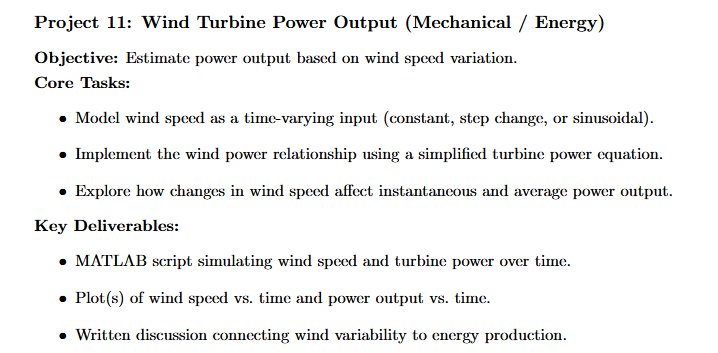

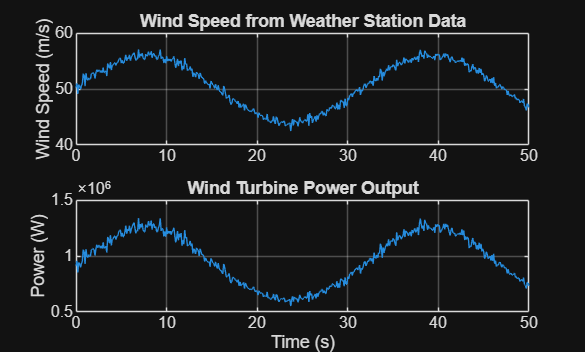

clc; clear; close all

% ---------------------------------------------------------
% USER INPUTS (Weather Station Data)
% ---------------------------------------------------------
v_mean = input('Enter mean wind speed from weather station (m/s): ');
v_amp  = input('Enter wind fluctuation amplitude (m/s): ');
rho    = input('Enter air density from weather station (kg/m^3): ');

% ---------------------------------------------------------
% CONSTANTS
% ---------------------------------------------------------
A = 12;        % rotor swept area (m^2)
Cp = 0.4;      % power coefficient

% ---------------------------------------------------------
% TIME VECTOR
% ---------------------------------------------------------
t = 0:0.1:50;

% ---------------------------------------------------------
% WIND SPEED MODEL (realistic atmospheric variation)
% ---------------------------------------------------------
v = v_mean + v_amp*sin(0.2*t) + 0.5*randn(size(t)); 
% sine wave = natural variation
% randn = turbulence / measurement noise

% Ensure wind speed is not negative
v(v < 0) = 0;

% ---------------------------------------------------------
% POWER CALCULATION
% ---------------------------------------------------------
P = 0.5 * rho * A * Cp * v.^3;

% ---------------------------------------------------------
% ANALYSIS
% ---------------------------------------------------------
P_avg = mean(P);
P_max = max(P);
P_min = min(P);

% ---------------------------------------------------------
% PLOTS
% ---------------------------------------------------------
figure

subplot(2,1,1)
plot(t, v)
title('Wind Speed from Weather Station Data')
ylabel('Wind Speed (m/s)')
grid on

subplot(2,1,2)
plot(t, P)
title('Wind Turbine Power Output')
ylabel('Power (W)')
xlabel('Time (s)')
grid on


% ---------------------------------------------------------
% OUTPUT RESULTS
% ---------------------------------------------------------
fprintf('\n--- Wind Turbine Analysis Results ---\n')


--- Wind Turbine Analysis Results ---


fprintf('Average Power: %.2f W\n', P_avg);

Average Power: 977716.04 W


fprintf('Maximum Power: %.2f W\n', P_max);

Maximum Power: 1338051.34 W


fprintf('Minimum Power: %.2f W\n', P_min);

Minimum Power: 552232.69 W
